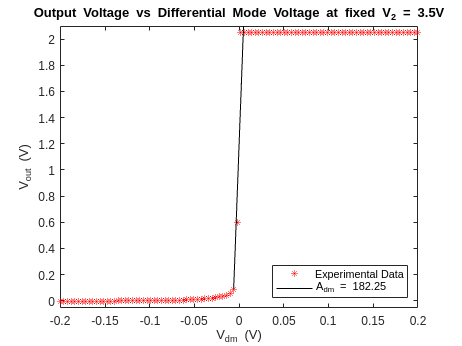

clear
load("data/AkshatsEXP2Data.mat","AK_EXP2_1_Vdm","AK_EXP2_1_Vout")
figure()
plot(AK_EXP2_1_Vdm,AK_EXP2_1_Vout,"r*","DisplayName","Experimental Data")
hold on
ylabel("V_{out} (V)")
xlabel("V_{dm} (V)")
title("Output Voltage vs Differential Mode Voltage at fixed V_{2} = 3.5V")
ylim([-0.05 2.1])

%fit line to slope
steep_idx = AK_EXP2_1_Vdm > -0.01 & AK_EXP2_1_Vdm < 0.01;
steep_x=AK_EXP2_1_Vdm(steep_idx);
steep_y=AK_EXP2_1_Vout(steep_idx);

p = polyfit(steep_x, steep_y, 1);

y_fit = polyval(p, steep_x);
plot(steep_x, y_fit, 'k',"DisplayName",sprintf("A_{dm} = %.2f",p(1)));
hold off
legend("Location","southeast")
print("-depsc","figures/exp2_part1.eps")

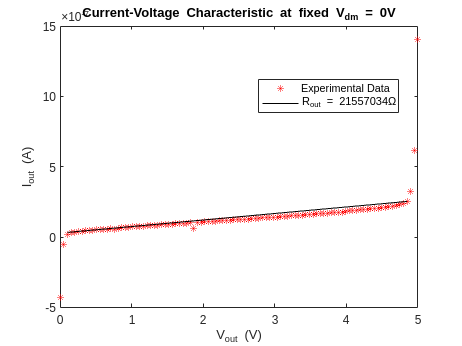

clear
load("data/AkshatsEXP2Data.mat","AK_EXP2_2_Iout","AK_EXP2_2_Vout")
plot(AK_EXP2_2_Vout,AK_EXP2_2_Iout,"r*","DisplayName","Experimental Data")
hold on
ylabel("I_{out} (A)")
xlabel("V_{out} (V)")
title("Current-Voltage Characteristic at fixed V_{dm} = 0V")
legend("Location","best")


shallow_idx = AK_EXP2_2_Vout >= 0.1 & AK_EXP2_2_Vout <= 4.85;
shallow_x=AK_EXP2_2_Vout(shallow_idx);
shallow_y=AK_EXP2_2_Iout(shallow_idx);

[f2, l2, m2, b2, n2] = linefit(shallow_x,shallow_y, 5e-4);
y_fit2 = m2 * shallow_x + b2;
r_val=1/m2;

plot(shallow_x, y_fit2, "k","DisplayName",sprintf("R_{out} = %.f\\Omega",r_val));

hold off
print("-depsc","figures/exp2_part2.eps")

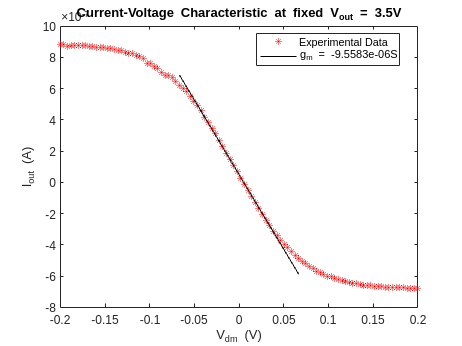

clear
load("data/AkshatsEXP2Data.mat","AK_EXP2_3_Iout_35","AK_EXP2_3_Vdm_35")
plot(AK_EXP2_3_Vdm_35,AK_EXP2_3_Iout_35,"r*","DisplayName","Experimental Data")
hold on
ylabel("I_{out} (A)")
xlabel("V_{dm} (V)")
title("Current-Voltage Characteristic at fixed V_{out} = 3.5V")
legend("Location","best")

linear_idx = AK_EXP2_3_Vdm_35 >= -0.07 & AK_EXP2_3_Vdm_35 <= 0.07;
lin_x=AK_EXP2_3_Vdm_35(linear_idx);
lin_y=AK_EXP2_3_Iout_35(linear_idx);

[f3, l3, m3, b3, n3] = linefit(lin_x, lin_y, 5e-4);
y_fit3 = m3 * lin_x + b3;

plot(lin_x, y_fit3, 'k', 'DisplayName', sprintf('g_{m} = %.5gS', m3));
hold off
print("-depsc","figures/exp2_part3.eps")